% Load your image
im = imread("Faces/db1_" + 1 + ".jpg");

% Process the image
outputImage = processImageWithSkinModel(im);

Arrays have incompatible sizes for this operation.

Error in sandbox2>nonlinearTransformation (line 62)
    C0(indices1) = Ci(indices1) + Wi * (Ci(indices1) - Ci(indices2));

Error in sandbox2>processImageWithSkinModel (line 43)
    Cb0 = nonlinearTransformation(Y, Cb, Wcb, WLcb, WHcb, Kl, Kh, Ymin, Ymax);

Related documentation


% Display the results or save the output image
imshow(outputImage);


## Norm

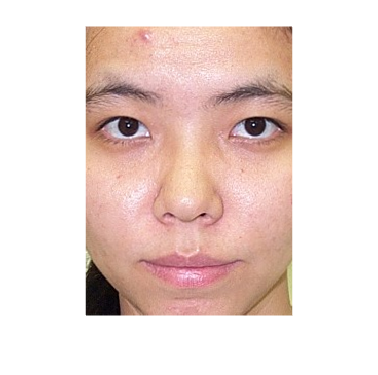

%Load face images from a folder
imageDir = '/Faces/';
images = dir(fullfile(imageDir, '*.jpg'));
numImages = length(images);

figure;
for i = 1:16
    % Load your image
    img = imread("Faces/db1_" + i + ".jpg");
    [eye1, eye2] = findEyes(img);
    norm = faceNormalization(img,eye1, eye2);
    imshow(norm)
    pause(1)
end

function processedImage = processImageWithSkinModel(inputImage)
    % Convert the input image to YCbCr color space
    ycbcrImage = rgb2ycbcr(inputImage);
    
    % Extract Y, Cb, and Cr channels
    Y = double(ycbcrImage(:,:,1));
    Cb = double(ycbcrImage(:,:,2));
    Cr = double(ycbcrImage(:,:,3));
    
    % Define the parameters
    Wcb = 46.97;
    WLcb = 23;
    WHcb = 14;
    Wcr = 38.76;
    WLcr = 20;
    WHcr = 10;
    Kl = 125;
    Kh = 188;
    Ymin = 16;
    Ymax = 235;
    cx = 109.38;
    cy = 152.02;
    angle = 2.53; % in radians
    ecx = 1.60;
    ecy = 2.41;
    a = 25.39;
    b = 14.03;

    % Implement the transformations
    Cb0 = nonlinearTransformation(Y, Cb, Wcb, WLcb, WHcb, Kl, Kh, Ymin, Ymax);
    Cr0 = nonlinearTransformation(Y, Cr, Wcr, WLcr, WHcr, Kl, Kh, Ymin, Ymax);

    % Apply the elliptical model
    [x, y] = ellipticalModel(Cb0, Cr0, cx, cy, angle, ecx, ecy, a, b);

    % Create the processed image
    processedImage = ycbcrImage;
    processedImage(:,:,2) = uint8(x); % Update the Cb channel
    processedImage(:,:,3) = uint8(y); % Update the Cr channel
end

function C0 = nonlinearTransformation(Y, Ci, Wi, WLci, WHci, Kl, Kh, Ymin, Ymax)
    C0 = Ci;
    indices1 = (Y(:,:) < Kl) | (Kh < Y(:,:));
    indices2 = Y(:,:) < Kl;
    indices3 = Kh < Y(:,:);

    % Apply the transformation to elements satisfying conditions
    C0(indices1) = Ci(indices1) + Wi * (Ci(indices1) - Ci(indices2));
    C0(indices2) = Ci(indices2) + Wi * (Ci(indices2) - Ci(indices3));

    % Handle the case where Ymin and Ymax are outside the specified range
    Y = max(min(Y, Ymax), Ymin);
end

% Define the elliptical model function
function [x, y] = ellipticalModel(Cb0, Cr0, cx, cy, angle, ecx, ecy, a, b)
    x = Cb0 - cx;
    y = Cr0 - cy;

    cosTheta = cos(angle);
    sinTheta = sin(angle);

    xPrime = cosTheta * x - sinTheta * y;
    yPrime = sinTheta * x + cosTheta * y;

    x = xPrime / ecx;
    y = yPrime / ecy;

    x = x / a;
    y = y / b;
end

